## 11. Gyakorlat

#### **1. Feladat**

Legyen $f(x)=\cos(x),~~(x\in [-\pi,\pi])$. Interpoláljuk az $f$ függvényt a $-\pi,0,\pi$ alappontokon globális bázisban, Hermite-féle peremfeltétellel: $f'(-\pi)=f'(\pi)=0$.

    a) Készítsük el a LER-t,

    b) majd oldjuk meg MATLAB-bal, és rajzoljuk ki a megoldást. 

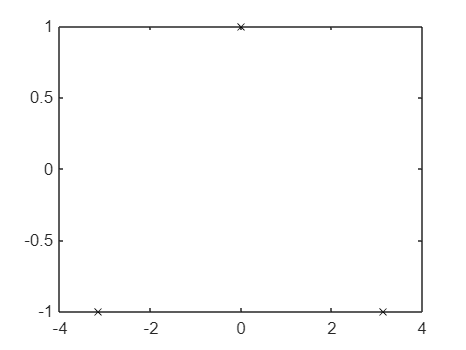

% Megoldás

#### **2. Feladat**

Határozzuk meg azt a természetes köbös spline-t, amely a $-2,-1,0,1$ pontokban rendre a $-1,0,1,0$ értékeket veszi fel. Keressük a spline-t globális bázisban!

    a) Készítsük el a LER-t,

    b) majd oldjuk meg MATLAB-bal, és rajzoljuk ki a megoldást.  

% Megoldás


### **Általánosított inverz és legkisebb négyzetek módszere**

Általánosított inverz mátrix számítása MATLABBAL:

`X = pinv(A):` $X=A^+$, az általánosított inverz mátrix.

#### **3. Feladat**

Legyen $A=\left[\begin{array}{c} 1 \\ 1 \\ \vdots \\ 1 \end{array}\right] \in \mathbb{R}^{m \times 1}$ és $B =\left[\begin{array}{cccc} 1 & 1 & \dots & 1 \end{array}\right] \in \mathbb{R}^{1 \times n}$. Állítsuk elő az $A^+, B^+$ mátrixokat!

m=5;
n=6;

A=ones(m,1)

A =      1
     1
     1
     1
     1


% Ap=pinv(A)
Ap=(A'*A)\A'

Ap =     0.2000    0.2000    0.2000    0.2000    0.2000



B=ones(1,n)

B =      1     1     1     1     1     1


% Bp=pinv(B)
Bp=B'/(B*B')

Bp =     0.1667
    0.1667
    0.1667
    0.1667
    0.1667
    0.1667


#### **4. Feladat**

Legyen $A=\left[\begin{array}{rr} 1 & -1 \\ -1 & 0 \\ 1 & 1\end{array}\right] \in \mathbb{R}^{3 \times 2}$, valamint $B=A^T$. Határozzuk meg mindkét esetben az általánosított inverzet! Milyen sejtést fogalmazhatunk meg ez alapján? 

A=[1,-1;-1,0;1,1];
Ap=(A'*A)\A'

Ap =     0.3333   -0.3333    0.3333
   -0.5000         0    0.5000



B=A';
Bp=B'/(B*B');

norm(Ap-Bp')

ans = 0

A MATLAB szinguláris felbontást megvalósító programja:

`[U,D,V] = svd(A): `, ahol $S=UDV^*$; $U$ és $V$ unitér mátrix.

#### 5. Feladat

Készítsük el a 4. feladat mátrixának az általánosított inverzét a szinguláris felbontás felhasználásával! 

% Megoldás

[U,D,V]=svd(A);
D

D =     1.7321         0
         0    1.4142
         0         0


Dp=zeros(size(D'));
Dp(1,1)=1/D(1,1);
Dp(2,2)=1/D(2,2);
Dp

Dp =     0.5774         0         0
         0    0.7071         0



Ap2=V*Dp*U'

Ap2 =     0.3333   -0.3333    0.3333
   -0.5000    0.0000    0.5000



norm(Ap-Ap2)

ans = 1.6068e-16